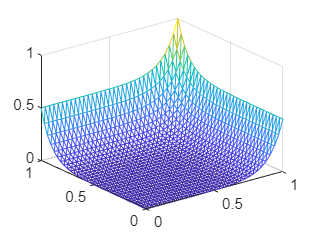

read_2D_mesh;                %read mesh
read_2D_input;               %read input

degree = 1;                  %input degree of shape functions
psi = bipolyLagrange(degree);  %obtain shape functions

K = zeros(nNodes);
F = zeros(nNodes,1);

for n=1:nElems
    nodelist = MESH.ConnectivityList(n,:);
    xcoords = MESH.Points(nodelist,1);
    ycoords = MESH.Points(nodelist,2);
    [Ke,Fe] = element2D(xcoords, ycoords, KofXY(n,1),BofXY(n,1),FofXY(n,1));   
    [K,F] = assemble2D(K,F,Ke,Fe,nodelist);
end

[K,F] = BCType1(boundaryNodes, boundaryValues, K, F);
U = K\F;

trimesh(MESH.ConnectivityList,MESH.Points(:,1),MESH.Points(:,2),U)
colormap default;
hold off;

% hold on
% x = linspace(0,1,100);
% y = x';
% z = (cosh(10*x)+cosh(10*y))/(2*cosh(10));
% surf(x,y,z)

[errorL2,errorMax] = error2D(MESH, U, nElems);

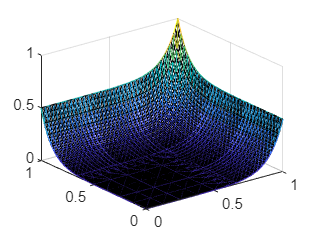

t = 0.8453

f = @() proj2_2;
t= timeit(f)

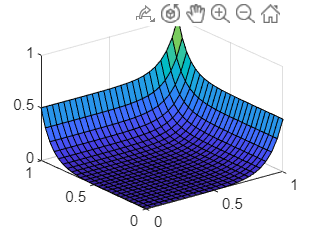

x = linspace(0,1,25);
y = x';
z = (cosh(10*x)+cosh(10*y))/(2*cosh(10));
surf(x,y,z)

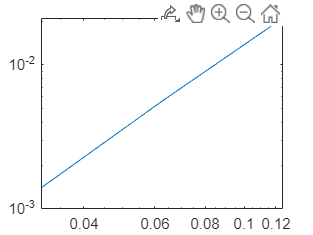

h = [0.1250 0.0625 0.0313]';
L2 = [0.0212 0.0056 0.0014]';
Linf = [0.0974 0.0342 0.0102]';
loglog(h, L2)

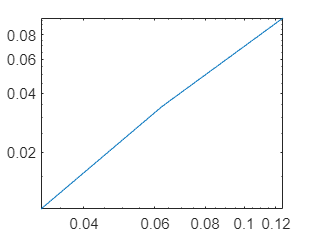

loglog(h, Linf)

polyfit(log(h), log(L2), 1)

ans =     1.9625    0.2369


polyfit(log(h), log(Linf), 1)

ans =     1.6295    1.0871


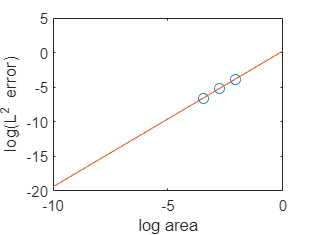

h = log([0.1250 0.0625 0.0313])';
L2 = log([0.0212 0.0056 0.0014])';
Linf = log([0.0974 0.0342 0.0102])';
plot(h,L2,'o')
p = polyfit(h,L2,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(p,x1);
plot(x1,y1)
xlabel('log area')
ylabel('log(L^{2} error)')
hold off

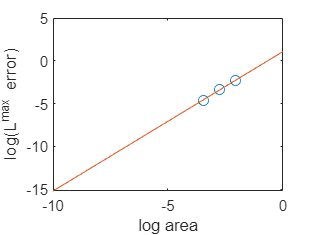


plot(h,Linf,'o')
pm = polyfit(h,Linf,1);
hold on
x1 = linspace(-10, 0);
y1 = polyval(pm,x1);
plot(x1,y1)
xlabel('log area')
ylabel('log(L^{max} error)')
hold off